1 ) Rolling sevens will be more probable than rolling snake eyes. Because the probability for rolling seven is is 6/36 = 1/6 and thee probability for rolling snake eyes is 1/36

2) The  convolution operator that determine the probability of the sum of 2 six sided dice is 

$P_{A+B} \left(x\right)=\sum_z^x P_A \left(z\right)P_B \left(x-z\right)$. 

I use the operator above to calculate the probability to get 1 to 12 .

for theprobability to get 1:  $\;P_{A+B} \left(1\right)=$$\sum_z^1 =P_A \left(1\right)\ldotp P_B \left(1-z\right)=\frac{1}{6}\ldotp 0=0$

for the probability to get 2: $P_{A+B} \left(2\right)=\sum_z^2 P_A \left(z\right)P_B \left(2-z\right)=P_A \left(1\right)\ldotp P_B \left(1\right)=\frac{1}{6}\ldotp \frac{1}{6}=\frac{1}{36}$

for the probability to get 3: $P_{A+B} \left(3\right)=\sum_z^3 P_A \left(z\right)P_B \left(3-z\right)=P_A \left(1\right)\ldotp P_B \left(2\right)+P_A \left(2\right)\ldotp P_B \left(1\right)=\frac{1}{36}+\frac{1}{36}=\frac{2}{36}$

for the probability to get 4: $P_{A+B} \left(4\right)=\sum_z^4 P_A \left(z\right)P_B \left(4-z\right)=P_A \left(1\right)\ldotp P_B \left(3\right)+P_A \left(2\right)\ldotp P_B \left(2\right)+P_A \left(3\right)\ldotp P_B \left(1\right)=\frac{3}{36}$

......

for the probability to get 10: $P_{A+B} \left(10\right)=\sum_z^{10} P_A \left(z\right)P_B \left(10-z\right)=P_A \left(6\right)\ldotp P_B \left(4\right)+P_A \left(5\right)\ldotp P_B \left(5\right)+P_A \left(4\right)\ldotp P_B \left(6\right)=\frac{3}{36}$

for the probability to get 11: $P_{A+B} \left(11\right)=\sum_z^{11} P_A \left(z\right)P_B \left(11-z\right)=P_A \left(6\right)\ldotp P_B \left(5\right)+P_A \left(5\right)\ldotp P_B \left(6\right)=\frac{2}{36}$

for the probability to get 2: $P_{A+B} \left(12\right)=\sum_z^{12} P_A \left(z\right)P_B \left(12-z\right)=P_A \left(6\right)\ldotp P_B \left(6\right)=\frac{1}{36}$

we get sum of dices(probability) by math :

 2(1/36)   3(2/36)   4(3/36)   5(4/36)   6(5/36)   7(6/36)   8(5/36)   9(4/36)   10(3/36)   11(2/36)   12(1/36) 

we get sum of dices and it probability by code:

clc; close all; clear;
pofdice = [1/6 1/6 1/6 1/6 1/6 1/6];
p = conv(pofdice,pofdice);
x = 2:12;
disp([x;p]);

    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000
    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278



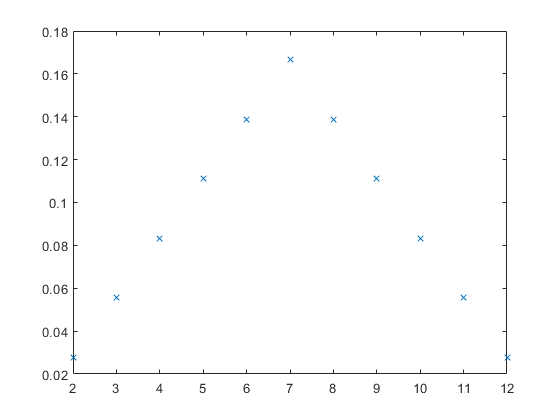

plot(x,p,"x");

3) Calculate the mean and the variance of the distribution in problem 2

The mean is the sum of all the possible outcome mutiply by it's probability values.

The variance is the sum of the difference between the possible outcome and mean, square it, and mutiply by it's probability values.

disp([x;p]);

    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000
    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278



A1=x.*p;
M = sum(A1);
disp("mean is "+M);

mean is 7


V=x-M;
V1=V.^2;
V2=V1.*p;
V3=sum(V2);
disp("variance is "+V3);

variance is 5.8333


4) Repeat 2, and graph the **average** of 10 dices. Is this is a Gaussian distribution? Explain in depth.

This is a Gaussian distribution is becaue the mean is the same with median and mode. The graph is symmetry about the center. It has bell curve as well. 

below is the graph for the average of 10 dices.

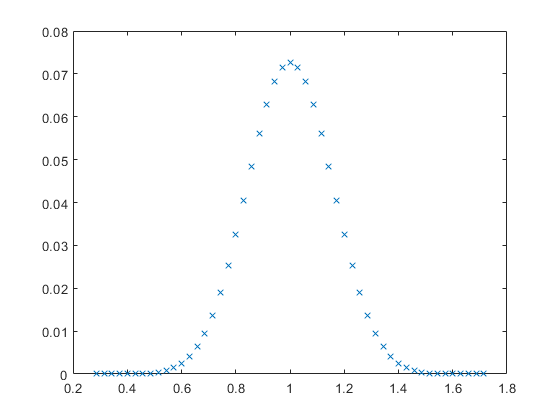

p2 = conv(p,p);
p3 = conv(p2,p2);
p4 = conv(p3,p);
x2=10:60;
x3 = mean2(x2);
x4 = x2./(x3);
plot(x4,p4,"x");

M1 = sum(x2.*p4);
disp("the mean for the probability distribution of 10 dice is at dice sum "+ M1);

the mean for the probability distribution of 10 dice is at dice sum 35


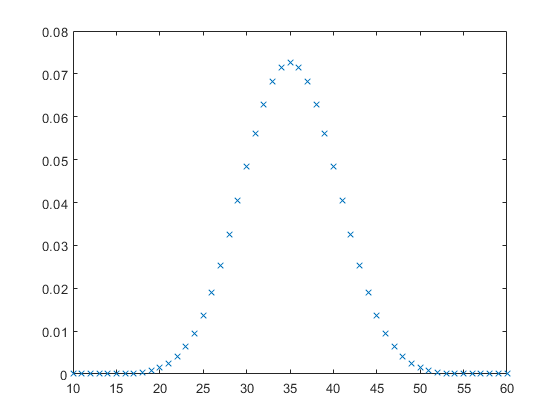

plot(x2,p4,"x");

5 ) I plot the distribution of the sum probabilities of  2 dice(blue), 4 dice(red), 8 dice(greed), and 10 dice(yellow) with average of a Gaussian. As you can see, When more dice are used the graph more Gaussian thus illustrating the idea that the sum and average of an initially Gaussian distribution is also Guassian. As the Guassian changes as a result of summing and averaging the standard deviation increases. You can see the standard deviation is geting bigger as the number of dice increase. This is important because as we integrate  over time, after the sum and average of a distribution the integral no longer gives the same sigma value.

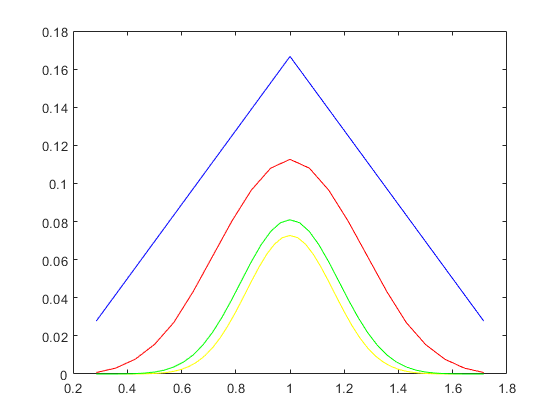

x5=mean2(x);
x6=4:24;
x7=mean2(x6);
x8=8:48;
x9=mean2(x8);
plot(x./x5,p,'color','b')
hold on
plot(x4,p4,'color','y')
plot(x6./x7,p2,'color','r')
plot(x8./x9,p3,'color','g')